imgOG = imread("girlpearl.jpg");
fprintf("Original Image:\n")

Original Image:


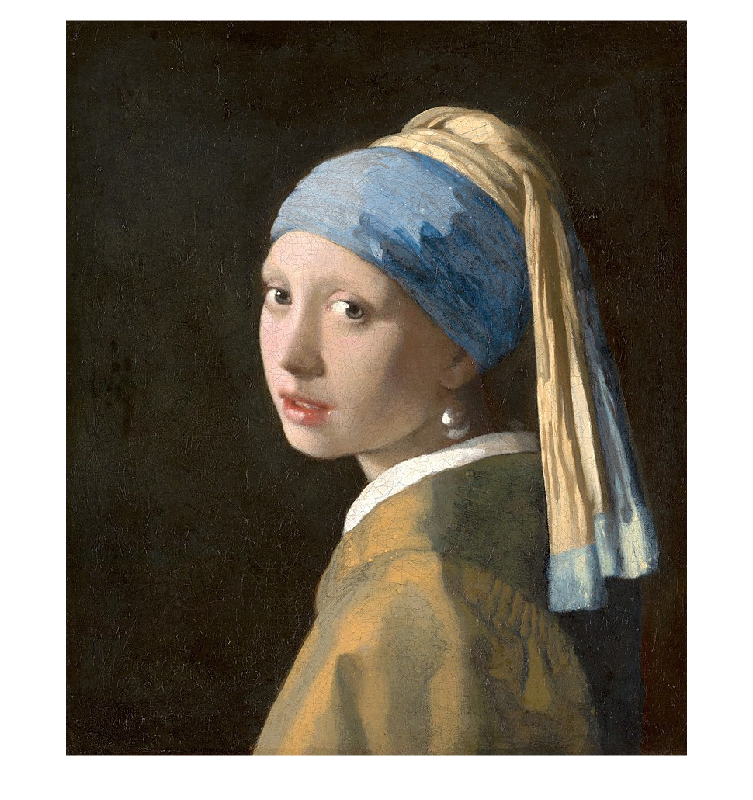

imshow(imgOG)

sizeOG = size(imgOG);
[n,d]=rat(sizeOG(2)/sizeOG(1),.05);
fprintf("Aspect Ratio For Original Image is %d:%d.\n", n,d)

Aspect Ratio For Original Image is 5:6.


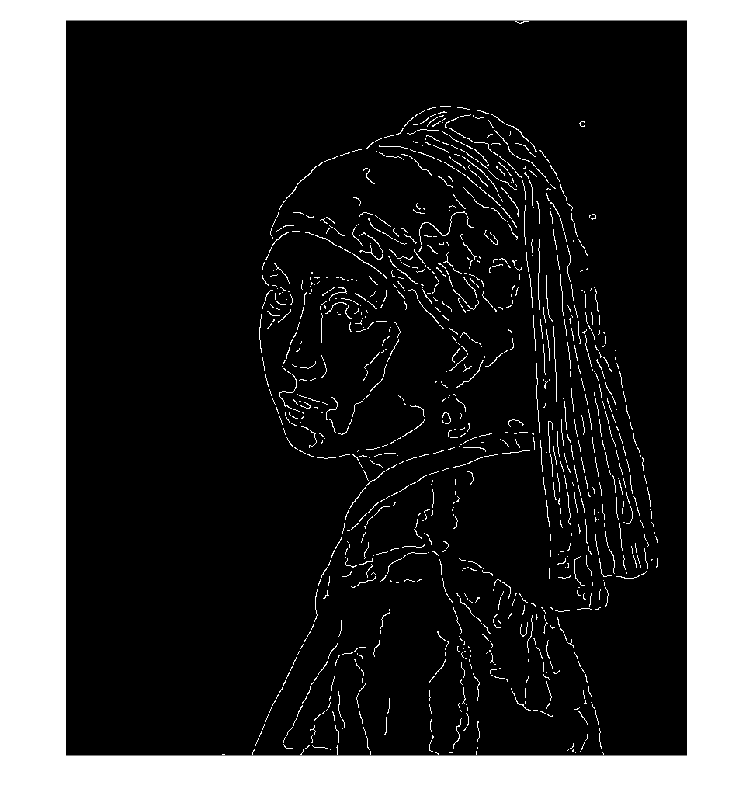

%numCol = 100;
%numRow = numCol*(n/d);
imgSmall = imresize(imgOG, [sizeOG(1), sizeOG(2)], "nearest");
%[X, map] = rgb2ind(imgSmall, 0.8,"nodither");
%[imgFinal, mapf] = imresize(X, map,(1/0.02), "nearest");
%fprintf("Pattern:")
%imshow(X, map);
%fprintf("Size of pattern is %d columns x %d rows.\n",numCol,numRow)
%imgColorKey  = 1:length(map);
%[ICK, mapck] = imresize(imgColorKey, map,80,"nearest"); 
%imshow(ICK, map)


img_lab = rgb2lab(imgOG);
img_abonly = img_lab(:,:,2:3);
img_abonly = im2single(img_abonly);
edges = edge(rgb2gray(imgOG), 'canny', [0.0388, 0.089], 3);
orgigthresh = [0.0188, 0.0469];
imshow(edges)

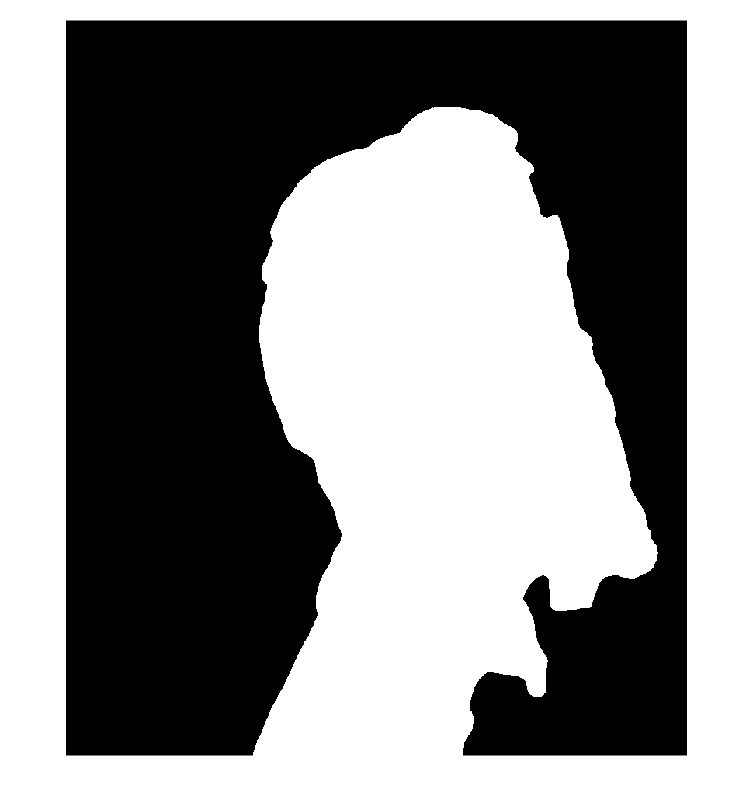

mask = zeros(947,800);
mask(50:end-50,50:end-50) = 1;
bw = activecontour(imgOG, mask, 1500, "Chan-vese","SmoothFactor",1,"ContractionBias",0.10);
imshow(bw)

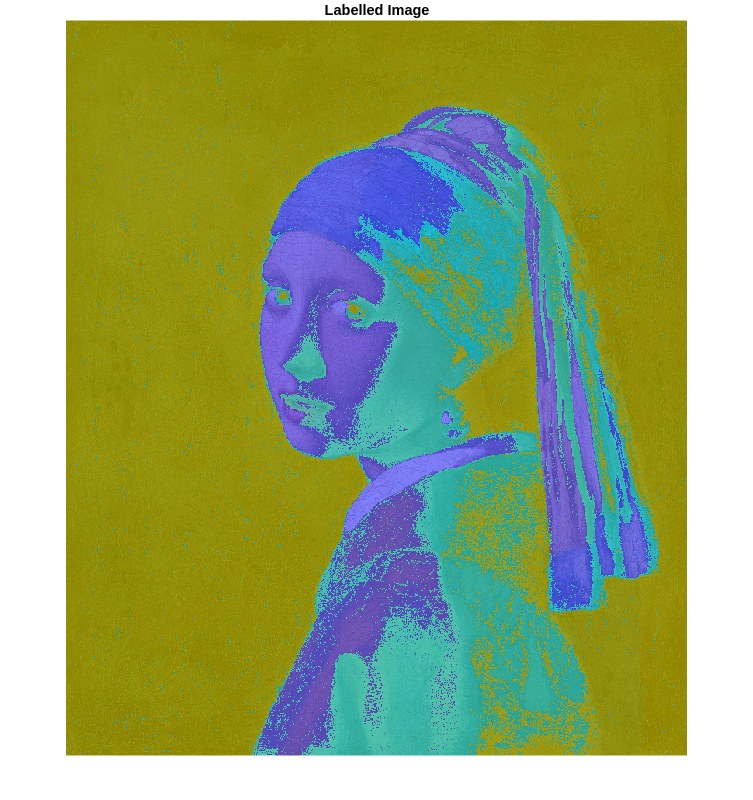


[L, C] = imsegkmeans(im2single(imgOG),3);
B = labeloverlay(imgOG,L);
imshow(B)
title("Labelled Image")